# Segmentation of Testing Dataset

This dataset is a subset of the testing dataset used in the publication. It contains 2000 image patches that are 64 x 64 pixels.

Please note that utilizing a GPU for this example is highly recommended, but not required.

clear, clc, close all

% The dataset files are in a multi-page TIFF format, so we need to get some
% additional information before loading the images
info = imfinfo('.\examples\testing-dataset\TestingImage.tiff');

% The intensity images (TestingImage.tiff) and ground truth images
% (TestingTruth.tiff) are paired
datasetImage = zeros(64,64,length(info),'uint16');
datasetTruth = zeros(64,64,length(info),'logical');

fprintf('Loading dataset (this may take a few minutes)...');

Loading dataset (this may take a few minutes)...


for i = 1:length(info)
    datasetImage(:,:,i) = imread('.\examples\testing-dataset\TestingImage.tiff',i);
    datasetTruth(:,:,i) = imread('.\examples\testing-dataset\TestingTruth.tiff',i);

    if mod(i,200) == 0
        fprintf('Loaded %i of %i\n',i,length(info));
    end
end

Loaded 200 of 2000
Loaded 400 of 2000
Loaded 600 of 2000
Loaded 800 of 2000
Loaded 1000 of 2000
Loaded 1200 of 2000
Loaded 1400 of 2000
Loaded 1600 of 2000
Loaded 1800 of 2000
Loaded 2000 of 2000


fprintf('Done\n')

Done


 Next, we can visualize the dataset

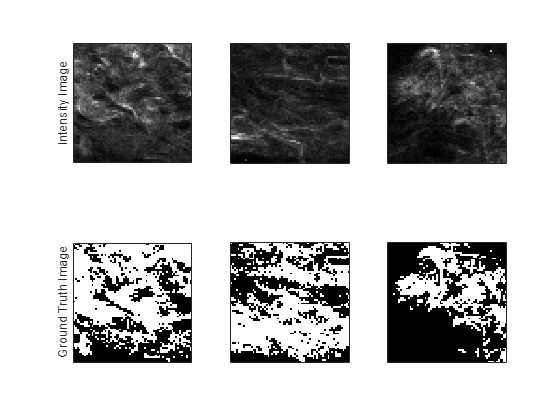

% Display 3 random pairs
randInd = randi(length(info),1,3);
figure;

for i = 1:3
    % Intensity image
    subplot(2,3,i)
    imagesc(datasetImage(:,:,randInd(i)));
    set(gca,'XTick',[]); set(gca,'YTick',[]);
    colormap gray; axis image;

    if i == 1
        ylabel('Intensity Image');
    end

    % Ground truth image
    subplot(2,3,i+3)
    imagesc(datasetTruth(:,:,randInd(i)));
    set(gca,'XTick',[]); set(gca,'YTick',[]);
    colormap gray; axis image;

    if i == 1
        ylabel('Ground Truth Image');
    end
end

Now we can load the trained convolutional neural network. Please note that this requires the `importONNXLayers` function, which is a free add-on for MATLAB. Using this function in the following code chunk will produce a warning and generate a "+collagen-cnn" folder due to incompatibility with upsampling. The network will still function as expected once loaded.

% Load the network
net = dlnetwork(importONNXLayers('.\files\collagen-cnn.onnx',TargetNetwork="dlnetwork"));

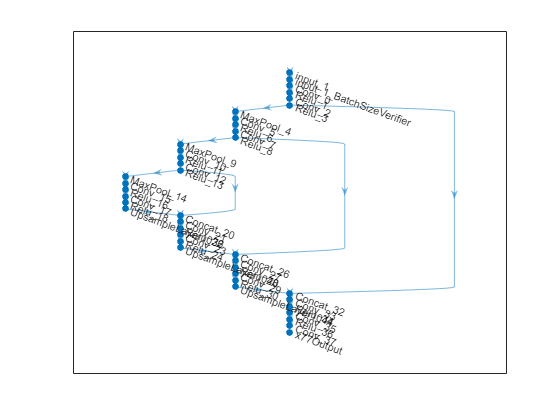


% Set up the sigmoid function
sigmoid = @(x) 1./(1+exp(-x));

% Plot the network architecture
figure;
plot(layerGraph(net));

Finally we can generate a forward pass for the intensity images

% Buffer masks into memory
mask = zeros(size(datasetImage),'logical');

% Check for GPU availability 
gpu = canUseGPU;

% Loop through each image
for i = 1:length(info)

    tempImage = dlarray(single(datasetImage(:,:,i))./8191,'SSCB');

    % Check for GPU availability
    if gpu
        tempImage = gpuArray(tempImage);
    end

    % Forward pass
    predMask = extractdata(forward(net,tempImage));

    if gpu
        predMask = gather(predMask);
    end
    
    % Calculate a probability map using the sigmoid function
    predMask = sigmoid(predMask);

    % Finally, apply a threshold of 0.56 (see publication for explanation)
    mask(:,:,i) = (predMask > 0.56);
end

Visualize the masks and compare to the ground truth image

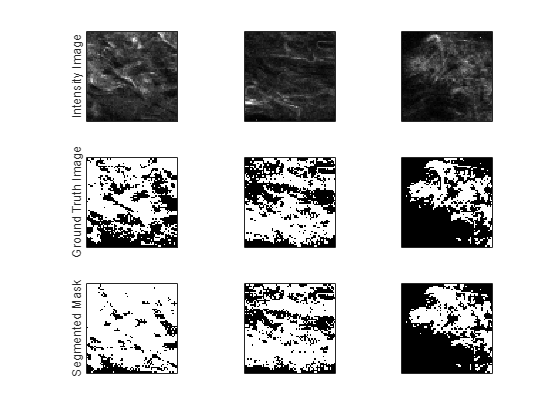

figure;

for i = 1:3
    % Intensity image
    subplot(3,3,i)
    imagesc(datasetImage(:,:,randInd(i)));
    set(gca,'XTick',[]); set(gca,'YTick',[]);
    colormap gray; axis image;

    if i == 1
        ylabel('Intensity Image');
    end

    % Ground truth image
    subplot(3,3,i+3)
    imagesc(datasetTruth(:,:,randInd(i)));
    set(gca,'XTick',[]); set(gca,'YTick',[]);
    colormap gray; axis image;

    if i == 1
        ylabel('Ground Truth Image');
    end

    % Generated mask
    subplot(3,3,i+6)
    imagesc(mask(:,:,randInd(i)));
    set(gca,'XTick',[]); set(gca,'YTick',[]);
    colormap gray; axis image;

    if i == 1
        ylabel('Segmented Mask');
    end
end